Построение графика несущей опоры 

% входные параметры
angle_1 = 65;
l1 = 22017; % длина участка 1
b = 6992;
h = 19991;

% l2 и l3 - вычисляются динамически 

% координаты потосянных точек 
x1_begin = 0;
y1_begin = 0;
y4_begin = h - 4457;
x4_begin = y4_begin/tand(angle_1) + b;
x4_end = b;
y4_end = 0;
x3_end = x4_begin;
y3_end = y4_begin;


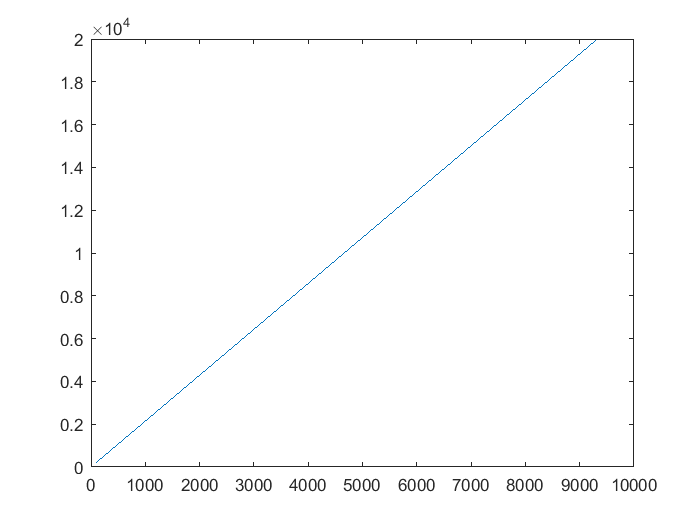

%% УЧАСТОК_1 - наклонный участок
% координаты начала и конца 
x1_end = l1*cosd(angle_1);
y1_end = l1*sind(angle_1);

% расчет шага 
N1 = 100; % количество точек не участке 1
dx_1 = l1/N1;

% заполнение масивов
for i = 1 : N1
    step1 = dx_1*i;
    x1(i) = cosd(angle_1)*step1;
    y1(i) = sind(angle_1)*step1;
end


% график
plot(x1, y1)

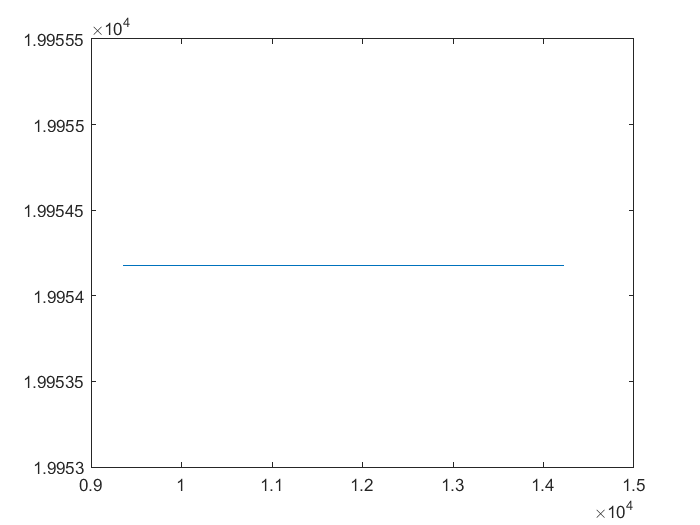

% УЧАСТОК 2 - горизонтальный участок
% координаты начала и конца 
x2_begin = x1_end;
y2_begin = y1_end;
x2_end = x4_begin;
y2_end = y1_end;

% расчет шага 
N2 = 100;
l2 = abs(x2_end - x2_begin);
dx_2 = l2/N2;

% заполнение масивов
for i = 1 : N2
    step2 = dx_2*i;
    x2(i) = x2_begin + step2;
    y2(i) = y2_begin;
end

plot(x2, y2)

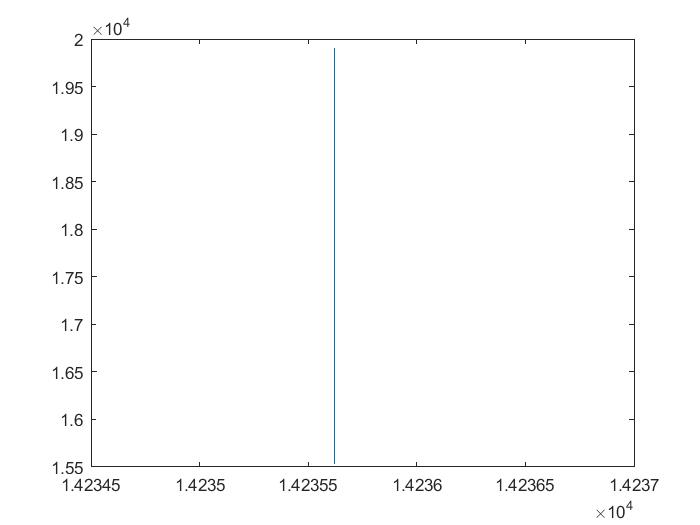

% УЧАСТОК 3 - вниз

% координаты начала и конца
x3_begin = x2_end;
y3_begin = y2_end;

% расчет шага 
N3 = 100;
l3 = abs(y3_end - y3_begin);
dx_3 = l3/N3;

for i = 1 : N3
    step3 = d x_3*i;
    x3(i) = x3_begin;
    y3(i) = y3_begin - step3;
end

plot(x3, y3);

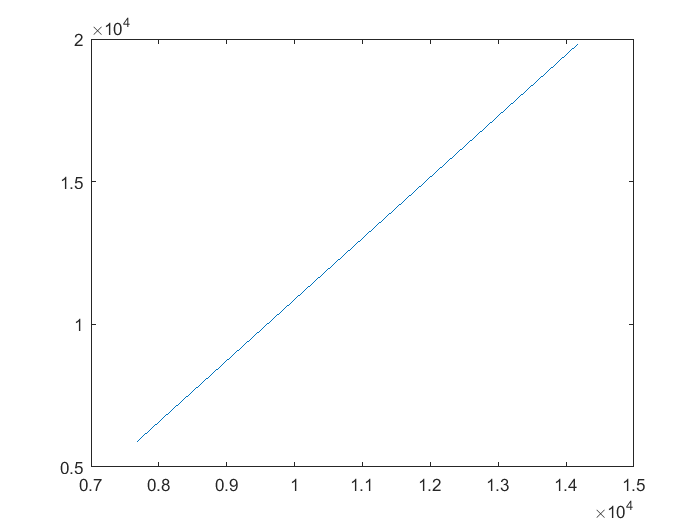

% УЧАСТОК 4 - наклон вниз
N4 = 100;
l4 = sqrt((x4_begin - x3_end)^2 + (y4_begin - y4_end)^2);
dx_4 = l4/N4;

for i = 1 : N3
    step4 = dx_4*i;
    x4(i) = x4_begin - step4*cosd(angle_1);
    y4(i) = y3_begin - step4*sind(angle_1);
end

plot(x4, y4);

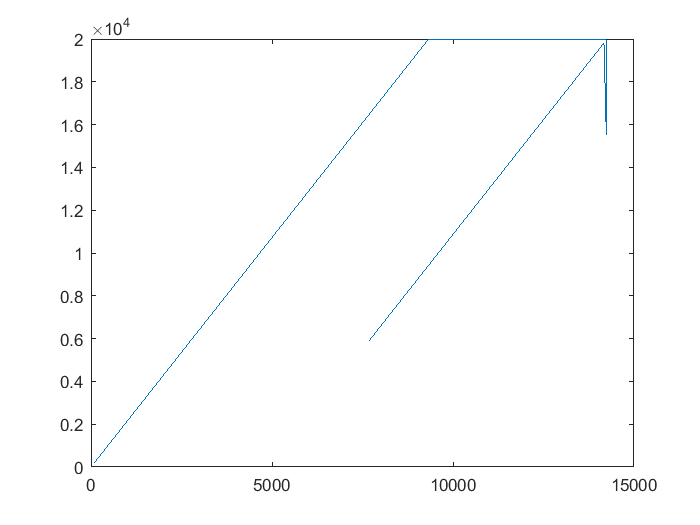

% cклеим все вместе 
X = horzcat(x1,x2,x3,x4);
Y = horzcat(y1,y2,y3,y4);
plot(X,Y)